% Create a time vector and initialize the trajectory parameters
t = linspace(0, 10, 100); % Time from 0 to 10 seconds
angular_velocity = 0.5;   % Angular velocity in rad/s
radius = 1;

% Define the constant speed in the X direction
speed_x = 3; % m/s

target_position = zeros(length(t), 3);
for i = 1:length(t)
    % Calculate the YZ plane position for the target in a circular trajectory

    target_position(i,:) = [speed_x*t(i); radius*cos(angular_velocity * t(i)); radius*sin(angular_velocity * t(i))];
end

% disp(target_position)

% Create a 3D trajectory plot
% figure;  % Create a new figure
% plot3(target_position(:,1),target_position(:,2), target_position(:,3), 'b', 'LineWidth', 2);  % Plot the trajectory in blue with a thick line
% grid on;  % Show a grid
% xlabel('X-axis');
% ylabel('Y-axis');
% zlabel('Z-axis');
% title('3D Trajectory Plot'); 

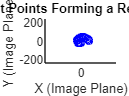

% Step 1: Initialise Camera Position
camera_position = [-10, 0, 0]; % Camera position in world coordinates
camera_orientation = [0,0,0]; % Camera orientation angles (roll, pitch, yaw) 

% Step 2: Define common camera intrinsic parameters
focal_length = 800; % Focal length of the camera
image_width = 640; % Width of the image plane
image_height = 480; % Height of the image plane
fov_horizontal = deg2rad(60); % 60 degrees horizontal FOV
fov_vertical = deg2rad(40);   % 40 degrees vertical FOV


% Initialize a variable to store the image coordinates of the target points
image_coordinates = zeros(length(t), 2);

% Define the dimensions of the rectangle
rectangle_width = 1;
rectangle_height = 0.3;

for i = 1:length(t)

    % Translate the target points to the camera coordinate system
    relative_positions = target_position(i,:) - camera_position;
    
    % Rotate the relative positions to align with the camera's orientation
    R = rotationMatrix(camera_orientation);
    rotated_positions = (R * relative_positions')';
    
    % Calculate the projection using the pinhole camera model for all four target points
    % image_x = (focal_length ./ rotated_positions(:,1)) .* rotated_positions(:,2);
    % image_y = (focal_length ./ rotated_positions(:,1)) .* rotated_positions(:,3);
    % image_coordinates(i, :) = [image_x, image_y];
    % % image_coordinates(i, :) = [image_x-rectangle_width/2 image_y+rectangle_height/2 image_x+rectangle_width/2 image_y+rectangle_height/2 ...
    % %                            image_x+rectangle_width/2 image_y-rectangle_height/2 image_x-rectangle_width/2 image_y-rectangle_height/2];
    % % image_coordinates(i, :) = image_coordinates(i, :) ./ rotated_positions(:,1)

    % Check if the point is within the camera's field of view
    if isWithinFOV(rotated_positions, fov_horizontal, fov_vertical)
        % Calculate the projection using the pinhole camera model
        image_x = (focal_length / rotated_positions(:,1)) * rotated_positions(:,2);
        image_y = (focal_length / rotated_positions(:,1)) * rotated_positions(:,3);

        image_coordinates(i, :) = [image_x image_y];
    else
        % Point is outside the field of view, set the image coordinates to NaN
        image_coordinates(i, :) = [NaN NaN];
        disp('Out of FOV')
    end
end


% Plot the target points' trajectories on the image plane using a for loop
figure;
hold on;
axis([-image_width/2, image_width/2, -image_height/2, image_height/2]);
xlabel('X (Image Plane)');
ylabel('Y (Image Plane)');
title('Projection of 4 Target Points Forming a Rectangle onto Image Plane');

% Define colors for each point
point_colors = ['bo', 'ro', 'go', 'mo'];

for i = 1:length(t)
    plot(image_coordinates(i, 1), image_coordinates(i, 2), 'bo', 'MarkerSize', 5);
    pause(0.01); % Add a pause for visualization (adjust as needed)
end


% for i = 1:length(t)
%     for j = 1:4
%         plot(image_coordinates(i, 2*j-1), image_coordinates(i, 2*j), point_colors(j), 'MarkerSize', 5);
%     end
%     pause(0.01); % Add a pause for visualization (adjust as needed)
% end


% % Plot the target point's trajectory on the image plane
% figure;
% plot(image_coordinates(:, 1), image_coordinates(:, 2), 'b', 'LineWidth', 2);
% xlabel('U (Image Plane)');
% ylabel('V (Image Plane)');
% title('Projection of 3D Point Trajectory onto Image Plane');
% grid on;
% axis([-image_width/2, image_width/2, -image_height/2, image_height/2]);


function R = rotationMatrix(angles)
    roll = angles(1);
    pitch = angles(2);
    yaw = angles(3);
    
    R_x = [1, 0, 0;
           0, cos(roll), -sin(roll);
           0, sin(roll), cos(roll)];
    
    R_y = [cos(pitch), 0, sin(pitch);
           0, 1, 0;
           -sin(pitch), 0, cos(pitch)];
    
    R_z = [cos(yaw), -sin(yaw), 0;
           sin(yaw), cos(yaw), 0;
           0, 0, 1];
    
    R = R_z * R_y * R_x;
end
% Function to check if a point is within the camera's FOV
function withinFOV = isWithinFOV(point, fov_horizontal, fov_vertical)
    if abs(atan2(point(2), point(1))) <= fov_horizontal/2 && abs(atan2(point(3), point(1))) <= fov_vertical/2
        withinFOV = true;
    else
        withinFOV = false;
    end
end